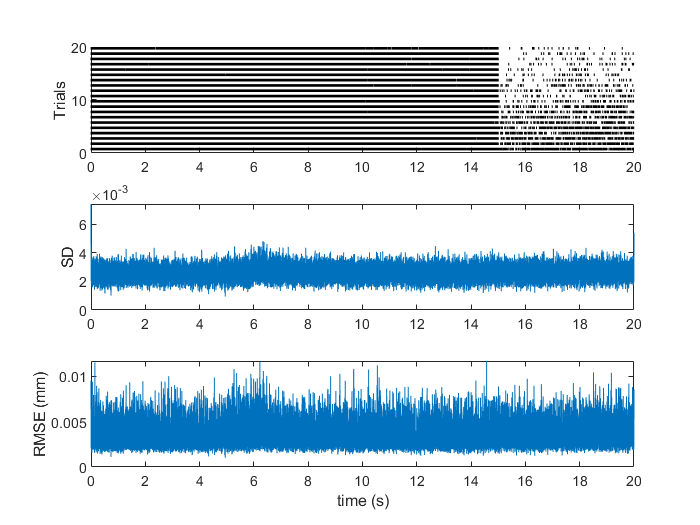

% raster = P.raster(:, start_stim:stop_stim);
A1 = subplot(3,1,1);

k = 0.5;
for j = 1:P.complete_trials
    l = find(P.raster(j,:)==1);
    spike_time = l/fs;
    for m = 1:length(spike_time)
        line([spike_time(m) spike_time(m)], [k k+0.5], 'Color', 'k', 'LineWidth', 0.01);
    end
    k = k+1;
end
ylabel('Trials');
% A1.Box = 'off';
% A1.XAxis.Visible = 'off';

% t = linspace(0,20,length(P.antennal_movement));
% plot(t(start_stim:stop_stim), P.antennal_movement(1:5, start_stim:stop_stim));
% ylabel('Antennal movement (mm)');

A2 = subplot(3,1,2);

stim_sd = std(P.antennal_movement, 0,1);
stim_mean = mean(P.antennal_movement,1);
coeff_var = 100* (stim_sd./stim_mean);

% plot(t(start_stim:stop_stim),coeff_var(start_stim:stop_stim));
% ylabel('% Coefficient of variation');

plot(t,stim_sd(:));
ylabel("SD")

A3 = subplot(3,1,3);

rmse = sqrt(sum(((P.antennal_movement(2:P.complete_trials,:)- P.antennal_movement(1,:)).^2),1)./(P.complete_trials-1));

plot(t,rmse);
ylabel('RMSE (mm)');
xlabel('time (s)');



linkaxes([A1 A2 A3  ], 'x');